# Lab #9 Higher Order IIR Filters

## Objectives

- Learn how to design and implement the recursion equation of a higher order IIR filter using automated design tools. 

- Demonstrate ability to obtain the impulse response and calculate the frequency response from an IIR filter recursion equation.

## Reading

    Review Chapters 2, 19 and 33 in Smith.      

## Intended Learning Outcomes

- Demonstrate low pass filtering of a signal using an IIR filter implemented in a microprocessor using a higher order filter

- Demonstrate band pass filtering of a signal using an IIR filter implemented in a microprocessor

## Lab 9 Arduino Code Base

The code base for Lab 9 is located on myCourses.  The filename is "Lab_09_IIR_Filters_Codebase.ino"

## **Overview -- Higher Order IIR Filters**

In class we discussed implementing a first order IIR filter using a recursion equation.  The filter roll off of a first order filter may not be sufficient in all applications and it is desirable to use filters with higher orders.  That is filters that have more poles and zeros in their transfer function.  In general a transfer function can be written as

#### 
$$H(z) = \frac{\sum_{k=0}^{M}a_k z^{-k}}{1-{\sum_{k=1}^N}b_kz^{-k}}$$


The poles of the filter are located at the roots of the equation in the denominator.  The zeros are located at the roots of the equation in the numerator.

The filter can be implemented using the difference equation

#### 
$$y[n] = \sum_{k=0}^{M}a_kx[n-k]+\sum_{k=1}^{N}b_ky[n-k]$$


Looking at the equation, the output is the sum of weighted and time delayed version of the input signal and weighted and time delayed versions of the output signal.  A block diagram of the implementation of the filter is shown below.

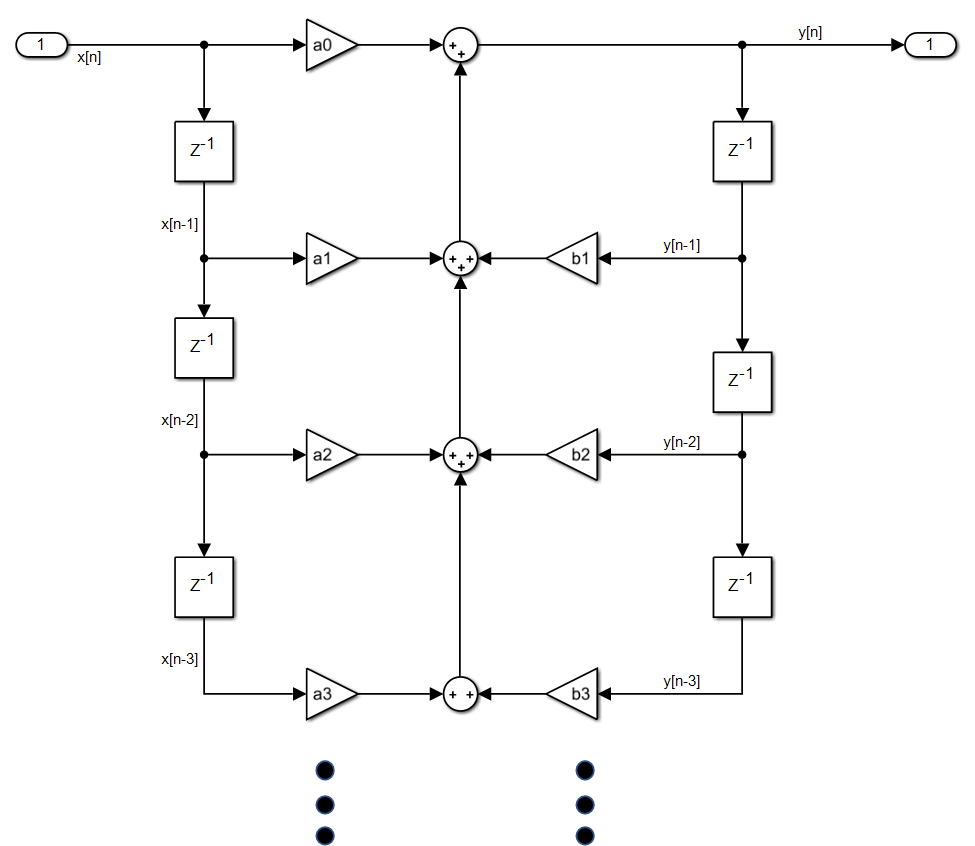

The location of the pole and zeros determines the impulse response and therefore the frequency response of the filter.  There are different types of filters that have different properties of their frequency response.  Two well-known responses are the Butterworth and the Chebyshev response.  They each have different locations of poles and zeros in their responses.  

How do you find the values of $a[n] $and $b[n]$?  The coefficients can be found by solving the equations for the roots and plugging in the desired locations for the poles and zeros, but this is complex and tedious.  Filter designers before us have created tables of values for use to help with the process.  However, there is yet a better way.  We can use MATLAB to generate the coefficients for us from the filter parameters such as the corner frequency and the desired ripple in the filter.

There is a MATLAB Live Script (originally written by Prof. Hochgraff and/or Prof Orlicki) that will do all the heavy lifting for you.  This is located in myCourses in the content section for this lab.  The file name is "IIR_Designer.mlx".  Download this file and locate it in your MATLAB working directory.

To run the script, you need to set the filter parameters.  That is:

1) Set the sampling rate of the filter.  This can be Hz or BPM (breaths per minute) or Normalized to 1.0

2) Select the filter type to either Butterworth or Chebyshev.

3)  Select the filter topology as one of Lowpass, Highpass, Bandpass or Bandstop

4)  If the filter type is Chebyshev then set the amount of ripple in decibels.  This is the amount of ripple in the passband of the filter.

Recall that Butterworth filters are maximally flat in the passband, but Chebyshev filters have ripple in the passband as a trade off for steeper roll off.  The ripple value is in decibels.  This value also defines the value of the attenuation at the corner frequency of the filter.

Below is a snapshot of the section in the MATLAB code with the two variables

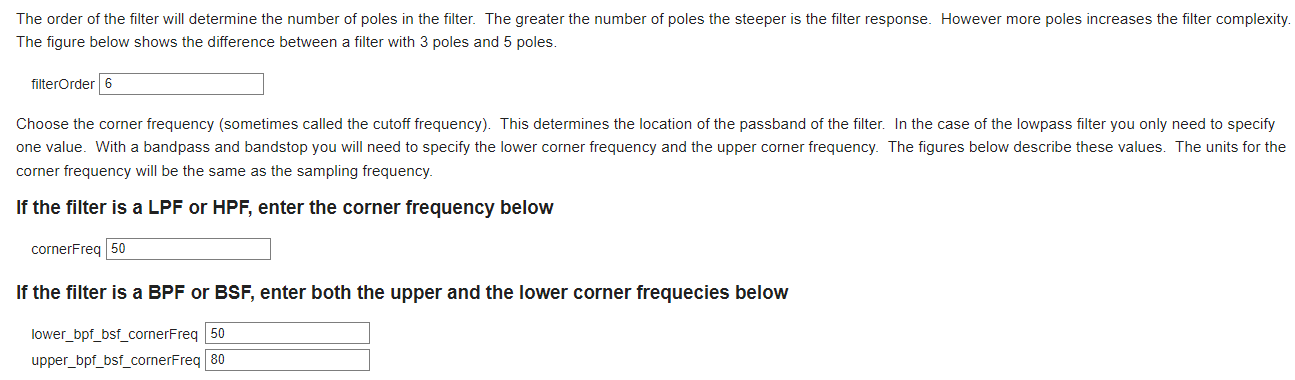

5)  Set the order of the filter next.  The higher the order of the filter, the steeper the transition region of the filter will be.

6)  Set the corner frequency of the filter.  For the Butterworth filter, this is the half power frequency.  This is the frequency at which the input power is attenuated by one-half.  The voltage attenuation at this point is 0.707.  For a Chebyshev filter this corresponds to the ripple bandwidth.  This is the highest frequency where the filter attenuation (in decibels) is the same as the ripple in the passband.

If you selected a bandpass or bandstop filter topology then set the lower corner frequency and the upper corner frequency in the next section

Here is a snapshot of the two code sections with the Butterworth filter selected

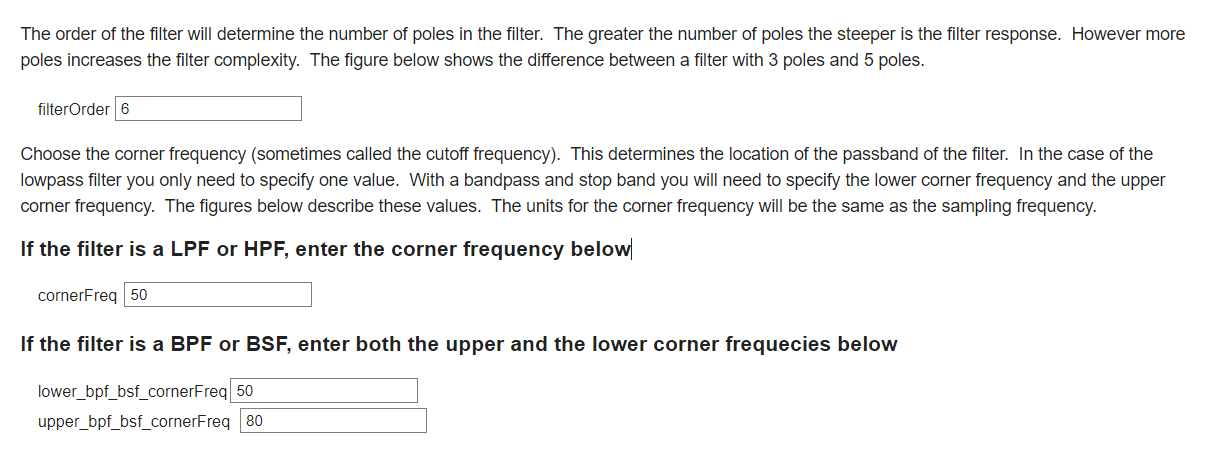

After setting the values above you can run the script.  The script prints out a bunch of interesting things in the command window and draws a graph of the impulse response and the frequency response of the filter.  These are helpful in making sure you get what you wanted.

We are going to create two different versions of the filters, direct IIR and Second Order Sections (SOS).  The direct version of the filter implements the difference equation as one complete equation from the entire transfer function.

#### 
$$H(z) = \frac{\sum_{k=0}^{M}a_k z^{-k}}{1-{\sum_{k=1}^N}b_kz^{-k}}$$


#### 
$$y[n] = \sum_{k=0}^{M}a_kx[n-k]+\sum_{k=1}^{N}b_ky[n-k]$$


The SOS approach breaks the transfer function into multiple second order transfer functions and cascades them.

#### 
$$H(z) =g_1 \frac{a_{10}+a_{11}z^{-1}+a_{12}z^{-2}}{1-b_{11}z^{-1}-b_{12}z^{-2}}\times g_2 \frac{a_{20}+a_{21}z^{-1}+a_{22}z^{-2}}{1-b_{21}z^{-1}-b_{22}z^{-2}}$$


The filter is implemented using multiple second order difference equations in cascade.  This is the difference equation for the first part of the transfer function.

#### 
$$y_1[n]=a_{10}x[n]+a_{11}x[n-1]+a_{12}x[n-2]+b_{11}y[n-1]+b_{12}y[n-2]$$


The output of this second order difference equation is used as the input to the next second order difference equation

#### 
$$y_2[n]=a_{20}x[n]+a_{21}x[n-1]+a_{22}x[n-2]+b_{21}y[n-1]+b_{22}y[n-2]$$


This continues for each second order section.  For filters with an odd order (e.g. 5th, 7th, 11th, …) and additional single pole stage is included.  Each stage also has a gain parameter (g1, g2, etc..) that scales the stage output correctly.

The direct form of the IIR filter can be used to implement filters with fewer poles but has some stability limitations when creating higher order filters.

The MATLAB script conveniently writes some Arduino code for you (cool huh?).  Let’s look at the Arduino code for a minute.  Copy the Arduino C-code from myCourses into the Arduino IDE. The file name of the code base for this lab is "Lab_09_IIR_Filters_Codebase.ino"

Note that MATLAB uses a different notation from the text and from what I have written above.  It just swaps the a and b values.  That is in MATLAB, the coefficients in the numerator of the transfer function are the b’s and the coefficients in the denominator of the transfer function are the a’s.

Here is the C-Code  function that executes the IIR filter in direct form by implementing the difference equation.  It is annotated below.

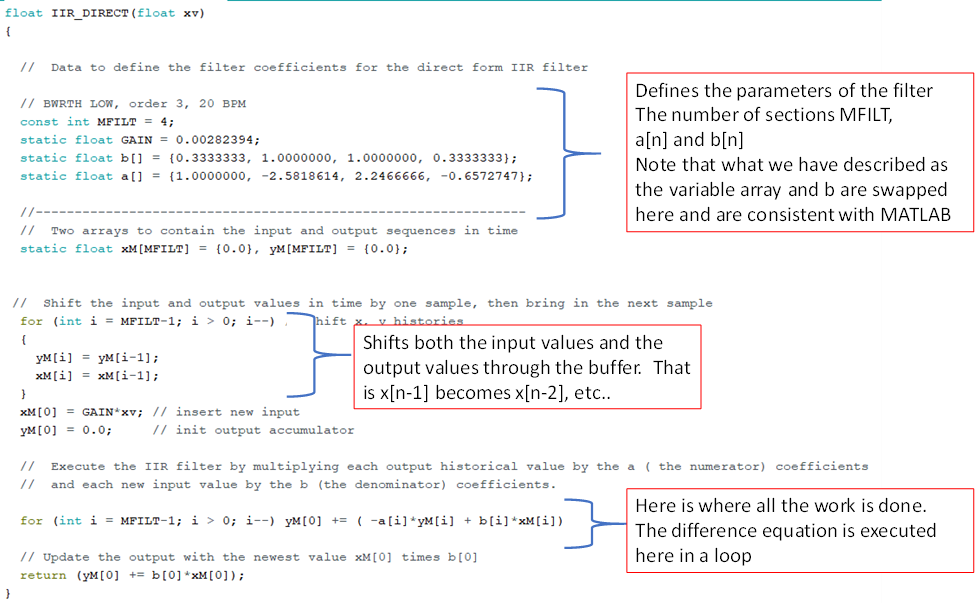

In order to create a new filter shape, all you need to do is to modify the variable definitions in the C-code at the beginning of the function.  Use the MATLAB Live script to compute the values of the variables. 

Start by setting the parameters of the filter in the MATLAB Live Script.  Then execute the MATLAB script by executing the script in the COMMAND window.  Type IIR_Designer and hit ENTER.

Copy the variable definitions for the DIRECT IIR Filter from the command window and paste into the C code.

NOTE THE STEPS:

SET the filter parameters in the IIR_Designer live script using the EDIT boxes.

EXECUTE the IIR_Designer in the COMMAND window and copy the computed parameters into your C-Code. 

The reason it is done this way is because you cannot copy the output of the script from the Live Editor file.

Here is an example MATLAB output for a 3rd order filter with a corner frequency of 25 bpm.  If you were using this you would copy this into the variable declaration code in the Arduino C-code as in the example below.

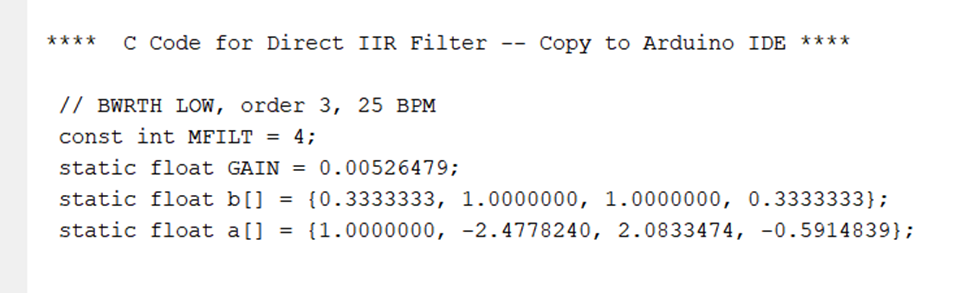

## Lab Procedure

In this lab you will create 6 different filters as shown in the table below and compare their results

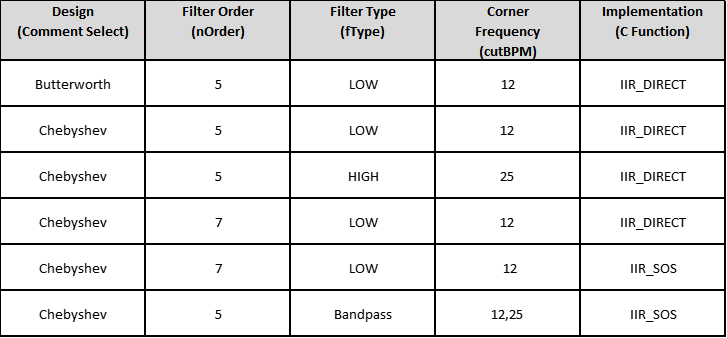

#### *Table **1*  *Filter Design Parameters*

#### **Implementing IIR Filters using the Direct Form **

In Lab 7, you evaluated the performance of FIR filters implemented using combinations of SINC based LPF and HPF sections.  When the filters were placed in series (cascade) a bandpass filter (BPF) resulted.  When the filters were placed in parallel a bandstop filter (BSF) was the result.  In an FIR filter, the transition from stopband to passband became quite sharp as the filter length increased from 20 taps to 80 taps for example. The tradeoff is that these sharper and longer FIR filters consume substantial memory and execution time. 

You will now design more resource efficient IIR filters.  They will use less memory, take fewer computations and execute quickly. They can have good performance parameters with sharp rolloffs.  However, they are subject to stability limitations depending on their implementation.

You will use a MATLAB based design tool that produces the IIR filter coefficients based on your specification of the filter type (e.g. high pass, low pass, or band pass), sample rate, cutoff frequency, passband ripple and pole count.  You will then implement the filters in your microprocessor and generate impulse and frequency responses to confirm stability and performance. 

#### **Choice of Filter Cutoff Frequencies**

In children, a breathing rate of greater than 50 breaths per minute can indicate pneumonia. In adults, a breathing rate of greater than 25 breaths per minute or fewer than 12 breaths per minute can indicate an abnormal condition. 

It is very difficult to physically sustain a breathing rate of greater than 50 breaths per minute. Therefore, in this lab, we will use a breathing rate limit of 25 breaths per minute as the abnormal threshold, which is suitable for adults.

### Part 1 -- Create a Butterworth 5th order Lowpass Filter 12 BPM

To detect a breathing rate below 12 breaths per minute we’ll use a lowpass filter.  When the breathing rate is below 12 bpm, the filter will pass the signal through.  Energy within this passband indicates a low breathing rate.  In the IIR_Designer MATLAB tool for designing low pass filters, set the following parameters:

Sampling Frequency -- 600 BPM

Filter Type -- Butterworth

Filter Topology -- Lowpass

Ripple dB -- Not used for Butterworth filters (leave setting)

Filter Order -- 5

Corner Frequency -- 12  (This is 12 BPM)

Lower BPF/BSF Corner Frequency -- Not used for LPF (leave setting)

Upper BPS/BSF Corner Frequency -- Not used for LPF (leave settting)

order of the filter (nOrder) to 5.  Then set the corner frequency of the filter to 12 bpm.  

#### Step 1

Save the Live Script and Run the MATLAB script from the command window.   The script will generate plots of the frequency and impulse responses.  The output will be in the command window and have separate figures. 

#### Step 2

Copy the coefficients that are generated by the code from the command window for the direct form of the filter.   These are in the MATLAB command window.  An example of the values is shown here.

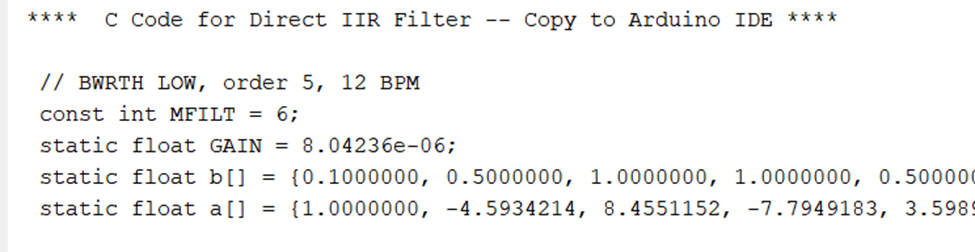

#### *Figure **2*  *MATLAB Generated Filter Coefficients*

#### Step 3

Copy this section in the Arduino IDE in the function IIR_DIRECT as shown in Figure 3 below

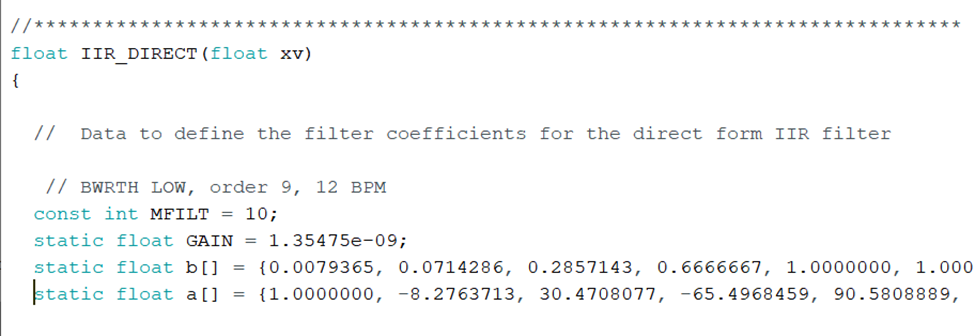

#### *Figure **3*  *Variable Declarations Copied to the Arduino IDE*

#### Step 4

In the C-code select the input to be the impulse response by uncommenting the impulse response test input generator line.  Also make sure that the filter function being selected is the IIR_DIRECT function.  These are shown in Figure 4 below.

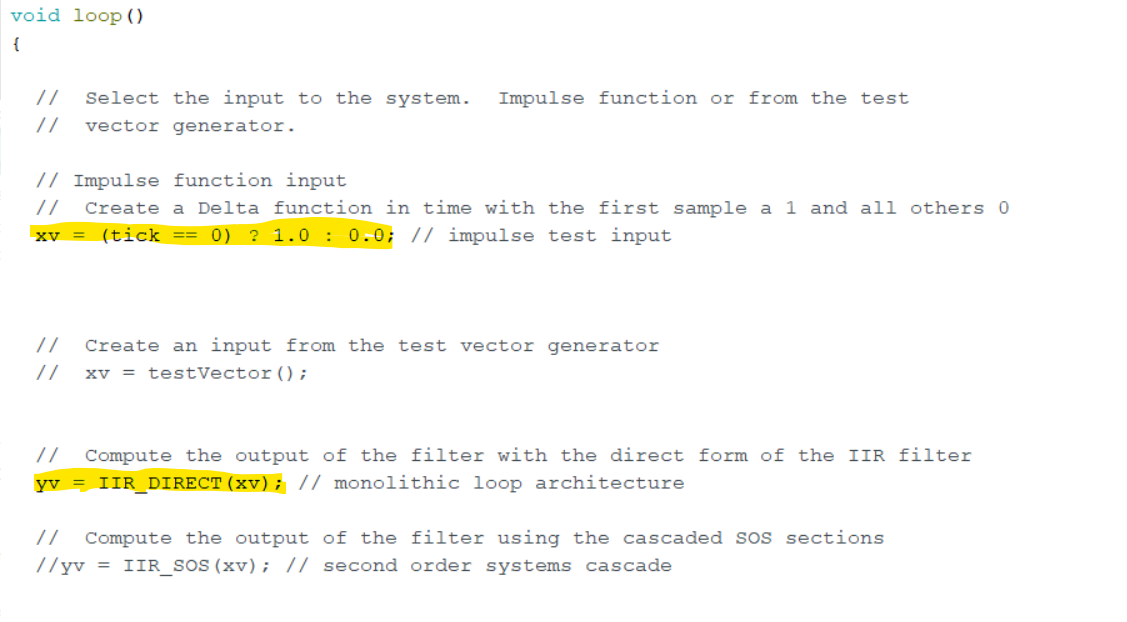

#### *Figure **4*  *C-Code Showing Impulse Response Input and IIR_Direct function selections*

#### Step 5

In the C-Code, set the global variable DATA_LEN to 512 samples.  This will generate 512 samples of output which will make it convenient when performing the FFT in MATLAB.  The FFT requires sample lengths that are powers of 2, that is 64, 128, 256, etc..  Having the C-Code generate the correct number of samples makes it convenient when using the FFT function in MATLAB.

#### Step 6

Execute the C-code using the Arduino and capture the data in MATLAB using the CaptureArduinoData function and save the results in a file.  The first column will be the input to the filter (an impulse) and the second column will be the output of the filter.

Recall that the syntax for the CaptureArduinoData function is:

Make sure that you set the ComPort and the BaudRate correctly.  In addition depending on the data being captured set the NumActivePlots parameters.  It is also helpful to set the GraphDelay parameter to a value about 50.

When you load the file you saved, a variable outData will be brought into the workspace.  The first column of outData is the sample number, the second column is the input to the filter (a delta function at time 0) and the third column is the response of the filter to that input, that is the impulse response of the filter.

Plot the impulse response of the fitler versus sample number.  Plot the magnitude of the frequency response in decibels vs Frequency in BPM (only from 0 to 50 BPM) by taking the FFT of the impulse response. Recall that the magnitude of the frequency response in decibels can be found from

#### 
$$Mag_{dB}= 20* log10(abs( Y ))$$


where Y is the frequency response and $Mag_{dB}$ is the magnitude of the frequency response in decibels.

Also recall that the frequency in BPM can be found from the sample number n using

#### 
$$Freq_{bpm} = \frac{n}{N} *f_s * 60 \frac{sec}{min}$$


where is the sample number, N is the total number of samples, fs is the sampling frequency (10 Hz).

Verify that the frequency response meets the requirements.

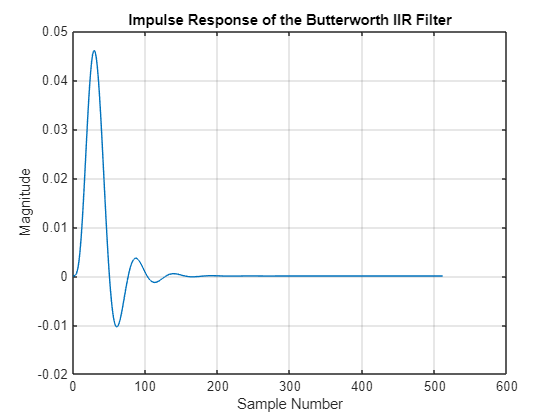


%  Load the MATLAB file
%  Plot the impulse response of the IIR Filter
%  Find the frequency response of the filter using the FFT and plot the
%  magnitude of the frequency response versus frequency in BPM.  Be sure
%  create a vector of frequencies representing the frequency in BPM


%  SOLUTION
% data = CaptureArduinoData('ComPort',9,'BaudRate',115200,'NumActivePlots',2,'GraphDelay',100);
clc;clear;close all
load('data/part1Data.mat');

numSamples = outData(2:end, 1);
BWRTHInput = outData(2:end, 2);
BWRTHimpResponse = outData(2:end,3);

figure;
plot(numSamples, BWRTHimpResponse); 
xlabel('Sample Number');
ylabel('Magnitude');
title('Impulse Response of the Butterworth IIR Filter');
grid on;

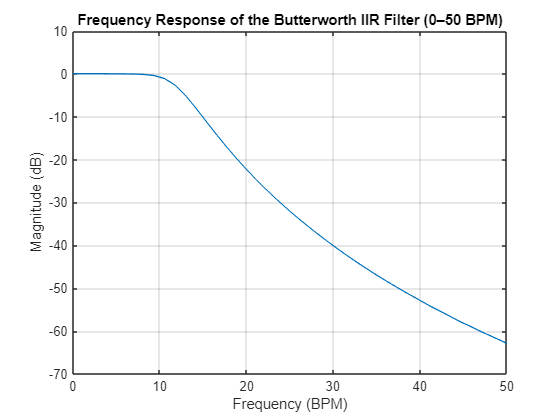


fs = 10; % Sample Frequency in Seconds
N = length(numSamples);

% Find the magnitude of the impulse response
BWRTHimpFFT = fft(BWRTHimpResponse);
BWRTHimpMagnitude = 20 * log10(abs(BWRTHimpFFT));

% Create frequency vector
BWRTHfreqHz = (0:N-1) * (fs / N);  % Frequency in Hz
BWRTHfreqBPM = BWRTHfreqHz * 60;  % Convert Hz to BPM

% Plot the magnitude of the frequency response (in dB) vs frequency in BPM (0 to 50 BPM)
figure;
plot(BWRTHfreqBPM, BWRTHimpMagnitude);
xlabel('Frequency (BPM)');
ylabel('Magnitude (dB)');
title('Frequency Response of the Butterworth IIR Filter (0–50 BPM)');
xlim([0 50]);
grid on;

### Part 2 -- Create a Chebyshev 5th order Lowpass Filter 12 BPM

#### Step 1

Repeat the steps above to create a 5th order Chebyshev lowpass filter with a cutoff frequency of 12 BPM.  Be sure to select the Chebyshev Filter for filterType.  Set the filter topology to LOWPASS.  Set the ripple of the Chebyshev filter to 1.0 dB.  See Table 1 for filter parameters.  

After setting the filter parameters, Run the IIR_Designer script from the command window.  Copy the  filter coefficients for the DIRECT IIR filter into the correct location in your C-code.

Capture the filter impulse response using the CaptureArduinoData function and save the output file.

#### Step 2

Again, plot the impulse response and the magnitude of the frequency response of the filter.

#### Step 3

Compare and comment on the results of the 5th order Butterworth and the 5th order Chebyshev filters by plotting their frequency responses on the same graph (only from 0 to 50 BPM).  Compare the two responses of the LPF's include your observations in your report.  Include a plot of just the  frequency response and your observations in your lab report.

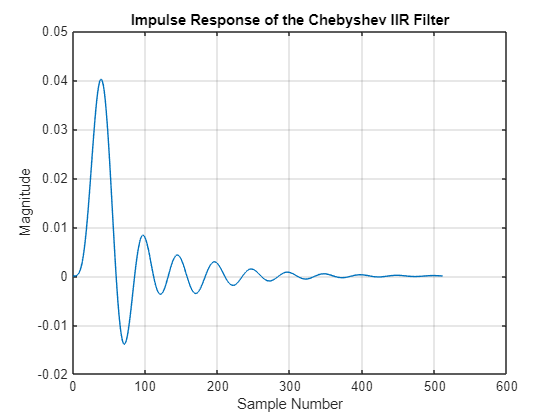

%  Load the MATLAB file
%  Plot the impulse response of the IIR Filter
%  Find the frequency response of the filter using the FFT and plot the
%  magnitude of the frequency response versus frequency in BPM.  Be sure
%  create a vector of frequencies representing the frequency in BPM


%  SOLUTION
% data = CaptureArduinoData('ComPort',9,'BaudRate',115200,'NumActivePlots',2,'GraphDelay',100);
load('data/part2Data.mat');

numSamples = outData(:, 1);
CHEBYInput = outData(:, 2);
CHEBYimpResponse = outData(:,3);

figure;
plot(numSamples, CHEBYimpResponse); 
xlabel('Sample Number');
ylabel('Magnitude');
title('Impulse Response of the Chebyshev IIR Filter');
grid on;

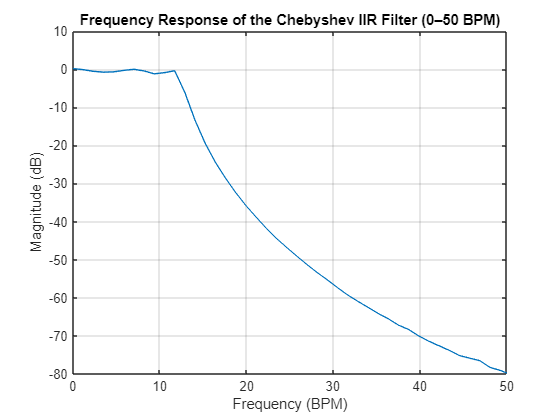


fs = 10; % Sample Frequency in Seconds
N = length(numSamples);

% Find the magnitude of the impulse response
CHEBYimpFFT = fft(CHEBYimpResponse);
CHEBYimpMagnitude = 20 * log10(abs(CHEBYimpFFT));

% Create frequency vector
CHEBYfreqHz = (0:N-1) * (fs / N);  % Frequency in Hz
CHEBYfreqBPM = CHEBYfreqHz * 60;  % Convert Hz to BPM

figure;
plot(CHEBYfreqBPM, CHEBYimpMagnitude);
xlim([0 50])
xlabel('Frequency (BPM)');
ylabel('Magnitude (dB)');
title('Frequency Response of the Chebyshev IIR Filter (0–50 BPM)');
grid on;

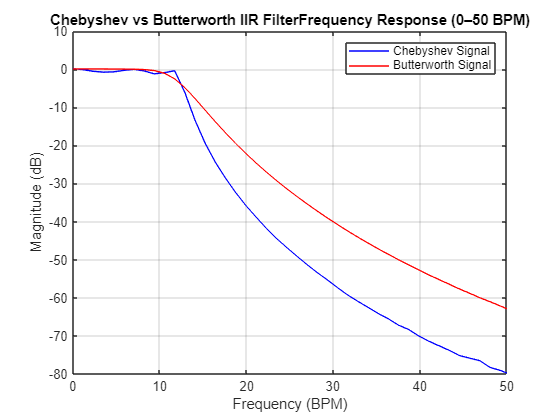


% Compare filters
figure;
plot(CHEBYfreqBPM, CHEBYimpMagnitude, 'b', 'DisplayName', 'Chebyshev Signal');
hold on;
plot(BWRTHfreqBPM, BWRTHimpMagnitude, 'r', 'DisplayName', 'Butterworth Signal');
xlim([0 50])
% xlim([0 300])
xlabel('Frequency (BPM)');
ylabel('Magnitude (dB)');
title('Chebyshev vs Butterworth IIR FilterFrequency Response (0–50 BPM)');

legend('show');
grid on;
hold off;

### Part 3 -- Create a Chebyshev 5th order Highpass Filter 25 BPM

To detect breathing rates greater than 25 bpm a highpass filter can be used to pass signals with a frequency greater than 25 bpm.   Energy detected in this frequency range indicates a high breathing rate.

#### Step 1

Repeat the steps in Part 1 above to create a 5th order Chebyshev highpass filter with a cutoff frequency of 25 BPM.  Set the ripple of the Chebyshev filter to 1.0 dB (variable R).  See Table 1 for the filter parameters.

#### Step 2

Capture the data in MATLAB and plot the impulse response and the magnitude of the frequency response in decibels of the filter.

#### Step 3

Compare the response of the HPF to the desired response (corner frequency, ripple ).  Include plots of the frequency response (only from 0 to 50 BPM) and your observations in your lab report.

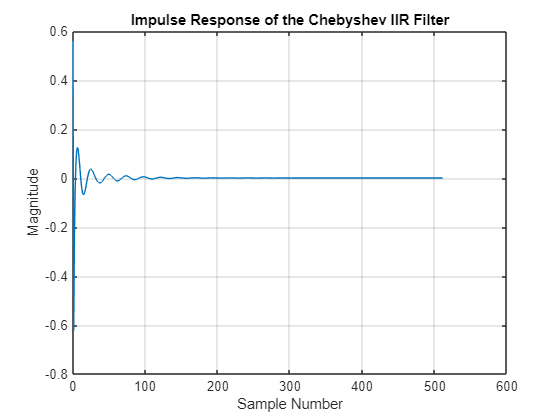

%  Load the MATLAB file
%  Plot the impulse response of the IIR Filter
%  Find the frequency response of the filter using the FFT and plot the
%  magnitude of the frequency response versus frequency in BPM.  Be sure
%  create a vector of frequencies representing the frequency in BPM


%  SOLUTION
% data = CaptureArduinoData('ComPort',9,'BaudRate',115200,'NumActivePlots',2,'GraphDelay',100);
load('data/part3Data.mat');

numSamples = outData(:, 1);
CHEBYBInput = outData(:,2);
CHEBYBimpResponse = outData(:,3);

figure;
plot(numSamples, CHEBYBimpResponse); 
xlabel('Sample Number');
ylabel('Magnitude');
title('Impulse Response of the Chebyshev IIR Filter');
grid on;

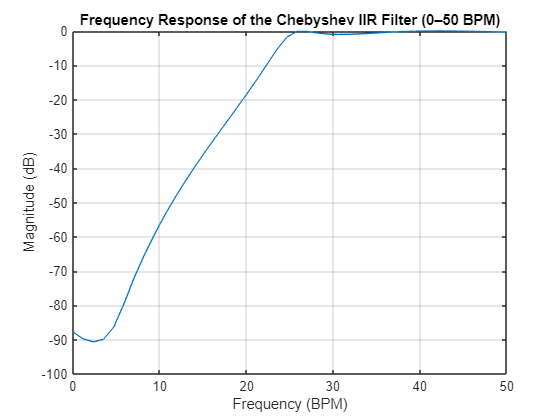


% Find the magnitude of the impulse response
CHEBYBimpFFT = fft(CHEBYBimpResponse);
CHEBYBimpMagnitude = 20 * log10(abs(CHEBYBimpFFT));

fs = 10; % Sample Frequency in Seconds
N = length(numSamples);

% Create frequency vector
CHEBYBfreqHz = (0:N-1) * (fs / N);  % Frequency in Hz
CHEBYBfreqBPM = CHEBYBfreqHz * 60;  % Convert Hz to BPM

figure;
plot(CHEBYBfreqBPM, CHEBYBimpMagnitude);
xlim([0 50])
% xlim([0 300])
xlabel('Frequency (BPM)');
ylabel('Magnitude (dB)');
title('Frequency Response of the Chebyshev IIR Filter (0–50 BPM)');
grid on;

### Part 4 – Investigate the Stability of Very High order IIR Filters

High order IIR filters can become unstable when implemented using the Direct Form.  In this section you’ll look at what happens with a high order IIR filter.  

#### Step 1

Using the MATLAB IIR_Designer script as above modify the filter parameters to create coefficients for an 7th order Chebyshev low pass filter with ripple of 1.0 dB at a corner frequency of 12 bpm.  Copy the coefficients to the C-Code.

#### Step 2

Execute the filter using the impulse response on the Arduino platform and capture the results in MATLAB.  Plot the impulse response of the filter.  Do not plot the frequency response.  What do you notice about the impulse response of the filter?  Is it stable?  Include a plot of the impulse response of the filter and your observations of the impulse response in your report.

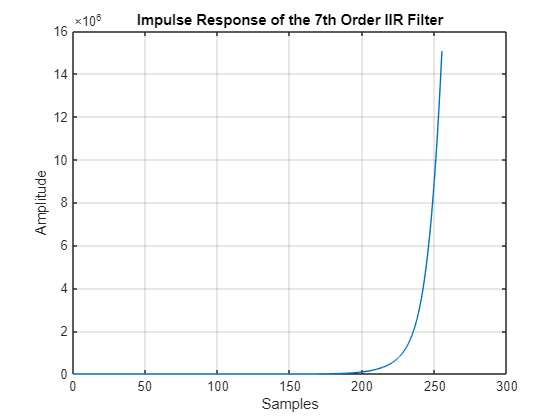

%  Load the MATLAB file
%  Plot the impulse response of the IIR Filter


%  SOLUTION
% data = CaptureArduinoData('ComPort',9,'BaudRate',115200,'NumActivePlots',2,'GraphDelay',100);
load('data/part4Data.mat');

numSamples = outData(:, 1);
CHEBYCInput = outData(:,2);
CHEBYCimpResponse = outData(:,3);

figure;
plot(numSamples, CHEBYCimpResponse);
xlabel('Samples');
ylabel('Amplitude');
title('Impulse Response of the 7th Order IIR Filter');
grid on;

### Part 5 – Implementing Higher Order IIR filters using Second Order Stages

An approach to implementing higher order IIR filters to maintain stability is to break up the filter into multiple second order stages.  The transfer function of the filter can be expressed as:

#### 
$$H(z) = \frac{\sum_{k=0}^{M}a_k z^{-k}}{1-{\sum_{k=1}^N}b_kz^{-k}}$$


Factoring the transfer function into second order polynomials results in the following transfer function where multiple second order stages are multiplied together.

#### 
$$H(z) =g_1  \frac{a_{10}+a_{11}z^{-1}+a_{12}z^{-2}}{1-b_{11}z^{-1}-b_{12}z^{-2}}\times g_2\frac{a_{20}+a_{21}z^{-1}+a_{22}z^{-2}}{1-b_{21}z^{-1}-b_{22}z^{-2}}\times ...$$


For each pole-zero pair in the total transfer function, there is a second order section in the factored transfer function.  If a filter has an odd order then an additional first order stage with one pole and one zero is needed. 

The MATLAB IIR_Designer script will generate the correct filter coefficients and gain values to properly implement the filter.  The coefficients displayed by MATLAB  in the command window for the 7th order filter using second order sections with a corner frequency of 12 BPM and 1.0 dB of ripple are shown below in Figure 5 and Figure 6.  The IIR filter implemented as second order sections is implemented in the C-Code function IIR_SOS.

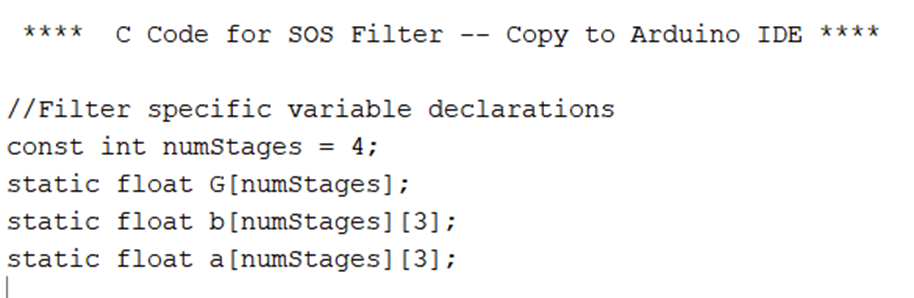

#### *Figure **5*  *First Part of the MATLAB Generated C-Code*

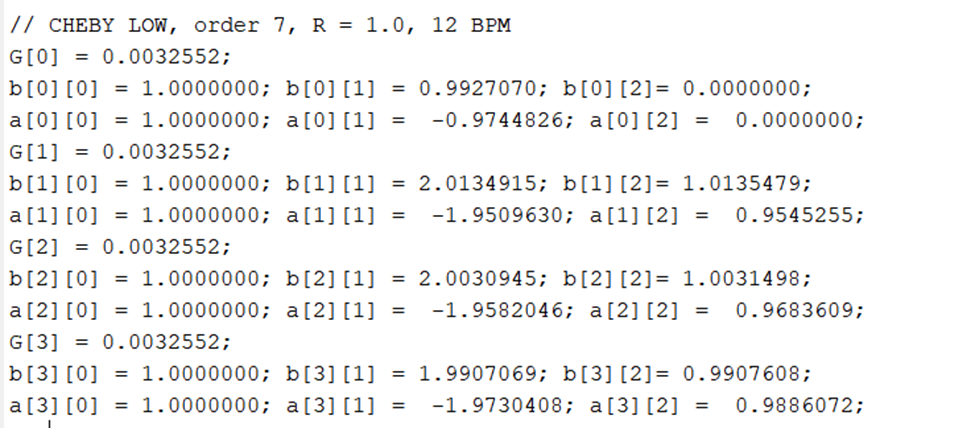

#### *Figure **6*  *Second Part of the C-Code Generated by MATLAB -- Variable Definitions*

#### Step 1

Copy the two code sections generated by MATLAB into the Arduino C-Code.  NOTE that there is some C-Code between these two sections that is needed, so don’t delete this code.

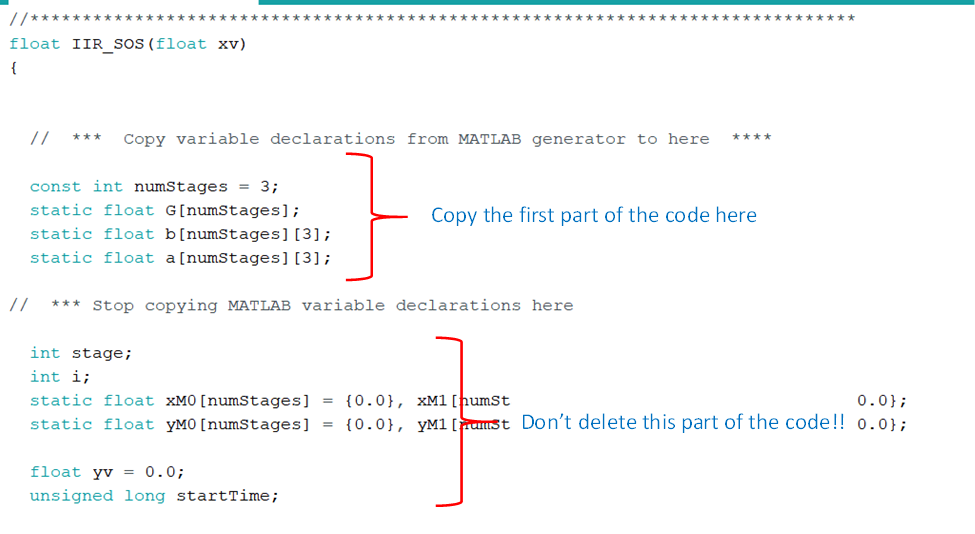

Copy the coefficient variable definitions into the second part of the C-code shown below in the function IIR_SOS

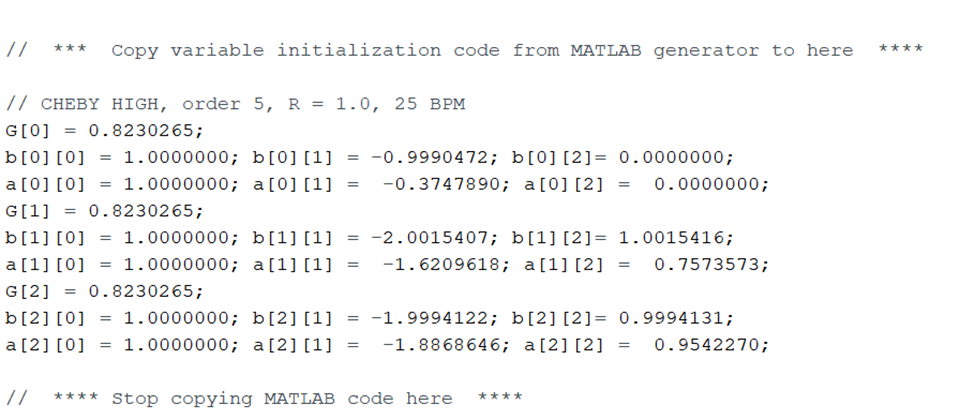

#### *Figure **7** IIR_SOS Coefficient Definitions in the C-Code*

#### Step 2

In the loop() function of the C-Code Comment out the line that calls the IIR_DIRECT function on the input variable and uncomment the line that calls the IIR_SOS function.

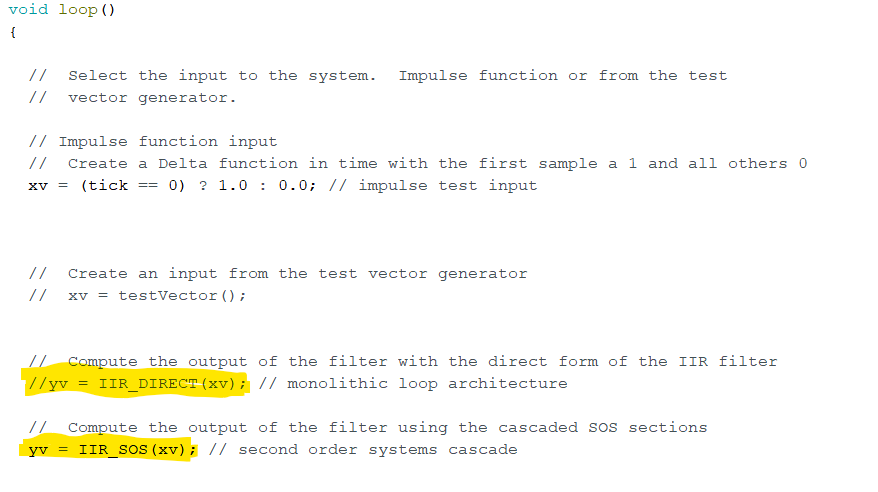

#### Step 3

Using the impulse response as the input signal, execute the C-Code on the Arduino platform.  Capture the impulse response of the filter in MATLAB.  Plot the impulse response and the frequency response of the filter.

How does the impulse response of the 7th order filter implemented in second order stages compare to the impulse response of the 7th order filter implemented using the direct form of the filter?  Include your observations and plots of the impulse response and the frequency response of the filter in your lab report.

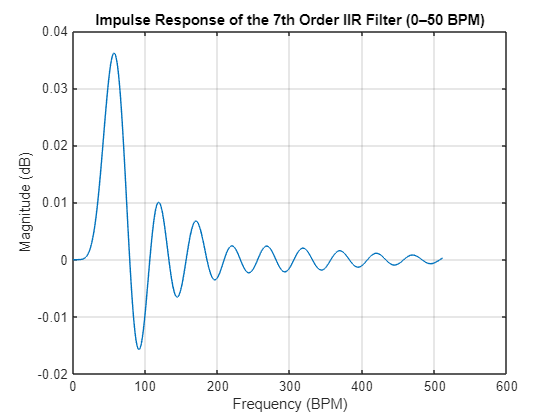

%  Load the MATLAB file
%  Plot the impulse response of the IIR Filter
%  Find the frequency response of the filter using the FFT and plot the
%  magnitude of the frequency response versus frequency in BPM.  Be sure
%  create a vector of frequencies representing the frequency in BPM


%  SOLUTION
% data = CaptureArduinoData('ComPort',9,'BaudRate',115200,'NumActivePlots',2,'GraphDelay',100);
load('data/part5Data.mat');

numSamples = outData(:, 1);
CHEBYDInput = outData(:,2);
CHEBYDimpResponse = outData(:,3);

figure;
plot(numSamples, CHEBYDimpResponse);
xlabel('Frequency (BPM)');
ylabel('Magnitude (dB)');
title('Impulse Response of the 7th Order IIR Filter (0–50 BPM)');
grid on;

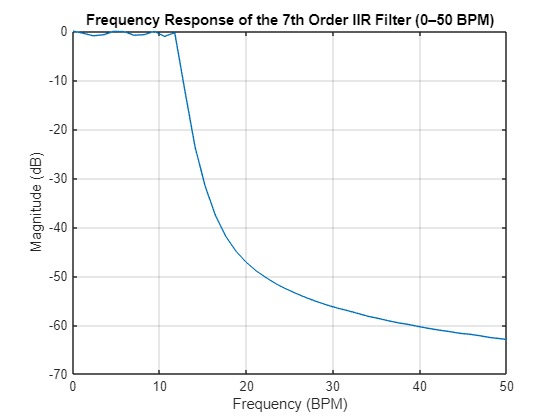


% Find the magnitude of the impulse response
CHEBYDimpFFT = fft(CHEBYDimpResponse);
CHEBYDimpMagnitude = 20 * log10(abs(CHEBYDimpFFT));

% Create frequency vector
CHEBYDfreqHz = (0:N-1) * (fs / N);  % Frequency in Hz
CHEBYDfreqBPM = CHEBYDfreqHz * 60;  % Convert Hz to BPM

figure;
plot(CHEBYDfreqBPM, CHEBYDimpMagnitude);
xlim([0 50])
% xlim([0 300])
xlabel('Frequency (BPM)');
ylabel('Magnitude (dB)');
title('Frequency Response of the 7th Order IIR Filter (0–50 BPM)');
grid on;

### Part 6 – Create an IIR Bandpass Filter using Second Order Stages

Normal breathing rate for an adult is between 12 bpm and 25 bpm.  Energy detected within this range of frequencies indicates that the breathing rate is normal.  To detect energy in this range a bandpass filter is needed to attenuate low frequency signals below 12 bpm and attenuate high frequency signals above 25 bpm while passing frequencies in between.

To create a bandpass filter, the IIR_Designer.mlx script is again used. The order of the filter is selected using the same edit box as before.  There are two corner frequencies defined for the bandpass filter, one of the lower corner and one for the upper corner.  These are set in the individual edit boxes.

#### Step 1

Select the Chebyshev Bandpass filter and set the ripple to 1.0 dB using the edit box.

MATLAB will create variable definitions as before for the Second Order Stages implementation.  The same C-Code function (IIR_SOS) is used for the lowpass filter and the bandpass filter.  The only difference is the value of the filter coefficients.

#### Step 2

Using the MATLAB IIR_Designer script generate coefficient values for a 5th order bandpass filter with a lower corner of 12 bpm and an upper corner of 25 bpm.  Use a 1.0 dB ripple filter.  Run the script in the command window.

#### Step 3

Copy the variable declaration code (part 1 of the code discussed above) and paste into the C-Code.

Copy the variable value definition code generated by MATLAB (part 2 of the code discussed above) and paste into the C-Code.

#### Step 4

Execute the filter using the impulse response as the input.  Capture the impulse response using MATLAB.  Plot the impulse and the frequency response of the bandpass filter.  Does the filter meet the requirements for the bandpass frequency range?  Include plots of just the bandpass frequency response in your report.

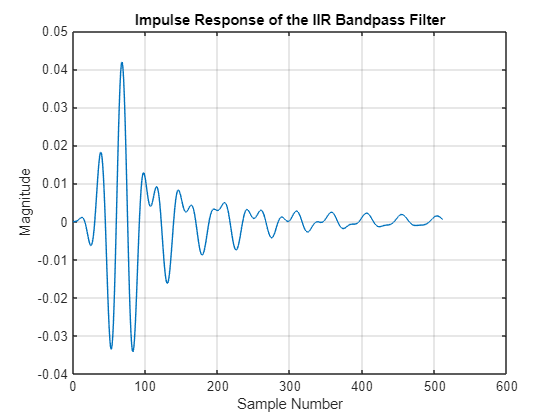

%  Load the MATLAB file
%  Plot the impulse response of the IIR Filter
%  Find the frequency response of the filter using the FFT and plot the
%  magnitude of the frequency response versus frequency in BPM.  Be sure
%  create a vector of frequencies representing the frequency in BPM


%  SOLUTION
% data = CaptureArduinoData('ComPort',9,'BaudRate',115200,'NumActivePlots',2,'GraphDelay',100);
load('data/part6Data.mat');

numSamples = outData(:, 1);
CHEBYEInput = outData(:,2);
CHEBYEimpResponse = outData(:,3);

figure;
plot(numSamples, CHEBYEimpResponse); 
xlabel('Sample Number');
ylabel('Magnitude');
title('Impulse Response of the IIR Bandpass Filter');
grid on;

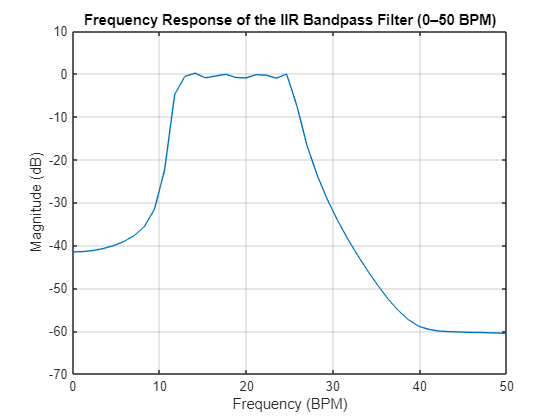


% Find the magnitude of the impulse response
CHEBYEimpFFT = fft(CHEBYEimpResponse);
CHEBYEimpMagnitude = 20 * log10(abs(CHEBYEimpFFT));

% Create frequency vector
CHEBYEfreqHz = (0:N-1) * (fs / N);  % Frequency in Hz
CHEBYEfreqBPM = CHEBYEfreqHz * 60;  % Convert Hz to BPM

figure;
plot(CHEBYEfreqBPM, CHEBYEimpMagnitude);
xlim([0 50])
xlabel('Frequency (BPM)');
ylabel('Magnitude (dB)');
title('Frequency Response of the IIR Bandpass Filter (0–50 BPM)');
grid on;

### Part 7 – Testing the IIR Bandpass Filter with Sinusoidal signals

To test the bandpass filter with some real signals, you’ll use the Test Vector Generator built into the C-Code.  The function *testVector* will geneate sequential sinusoidal signals.  To set the frequencies of the sinusoids, first set the number of frequencies by setting the variable NUM_BAND.  Then set the frequency values in array variable FBPM to the frequencies in BPM.  You can set the amplitudes of each sinusoid by changing the array bandAmp

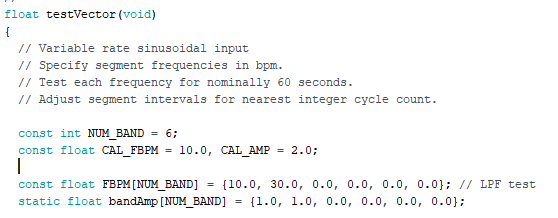

#### Step 1

Set the number of frequencies ot 6.  Set the frequencies of the 6 sinusoidal signals to 5, 10, 15, 20 ,30 and 70 bpm.  Set all of the amplitude values to 1.0.

#### Step 2

Comment out the impulse response as the input and comment in the test vector generator.  Set the global variable DATA_LEN to 3600 samples.  This is found at the beginning of the C-Code.

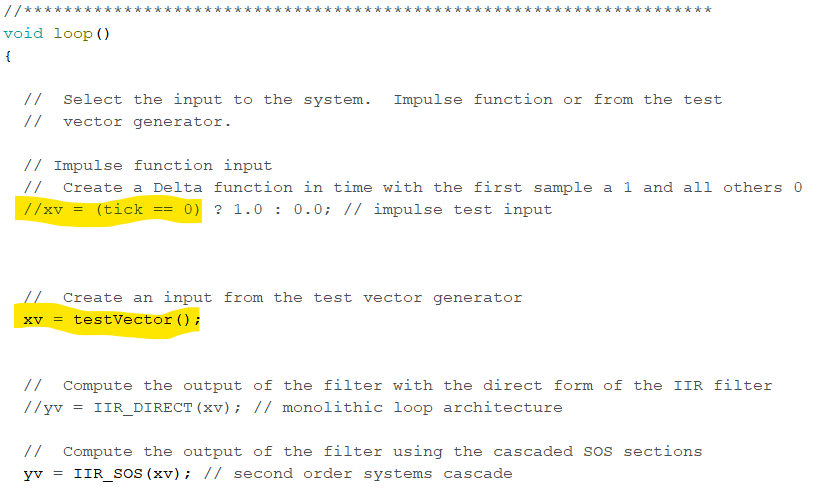

#### Step 3

Execute the C-Code on the Arduino and capture the results in MATLAB.  If you want to use active plots, you will have to add an additional parameter to the function call.  The parameter is 'GraphDelay', delayValue.  This will only update the plot every delayValue samples and prevents the serial port from over running and losing data.

#### Step 4

Plot the input samples and the output samples directly on the same plot (don’t take the FFT).  Compare the input sample values to the output sample values.

What do you observe about the output samples?  Is the filter operating as you would expect?

Include your plot and observations in your report.

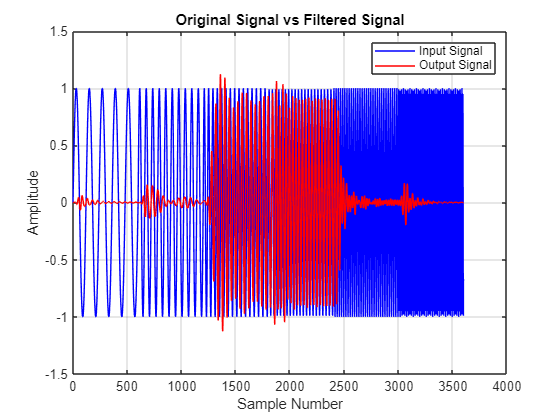

%  Load the MATLAB file
%  Plot the input signal and output signal of the filter on the same plot
%  Do not plot the FFT of the signal.


%  SOLUTION
% data = CaptureArduinoData('ComPort',9,'BaudRate',115200,'NumActivePlots',2,'GraphDelay',100);
load('data/part7Data.mat');

numSamples = outData(:, 1);
BandPassInput = outData(:,2);
BandPassimpResponse = outData(:,3);

% Input signal vs. Output signal
figure;
plot(numSamples, BandPassInput, 'b', 'DisplayName', 'Input Signal');
hold on;
plot(numSamples, BandPassimpResponse, 'r', 'DisplayName', 'Output Signal');

title('Original Signal vs Filtered Signal');
xlabel('Sample Number');
ylabel('Amplitude');
legend('show');
grid on;
hold off;

## Lab Report Discussion and Rubric

Your lab report is to be in IEEE format.  This lab has presented several ways to create low pass, high pass and band pass filters.  Consider the final project objective of being able to detect different rates of breathing.  Discuss in your report how you might combine various filter types to detect different rates of breathing.  How might you combine filtering with running variance calculations to determine whether a breathing rate falls into a low range, an acceptable mid-range and a dangerous high range above a threshold.